# Deep Learning mit MATLAB

% Die MATLAB Deep LEarning Toolbox stellt einige Funktionen zum Arbeiten mit Tiefen NEuronalen Netzen zur Verfügung.
% Stellen Sie sicher, das der Arbeitspfad richtig eingestellt ist, da sonst
% die Bilder nicht gefunden werden kann. 

filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(filename)


## Daten Laden und Data Store erstellen

filename = filename + "\Trainingsdaten\AusgeschnittenFürTraining\TD1_30erschild_festeTrainingsdatenOhneSchild";
imdsSchilder = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Explorative Datenanalyse

% numImgs = length(imdsZahlen.Files)
countEachLabel(imdsSchilder)

ans = 2×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder                408 
    Geschwindigkeitsbegrenzung_30     402 


%genau gleiche viele einträge von jedem Label
numPerLabel =min(countEachLabel(imdsSchilder).Count)

numPerLabel = 402

% Labels extrahieren
allLabels = unique(imdsSchilder.Labels);
balancedFiles = [];

for i = 1:numel(allLabels)
    label = allLabels(i);
    % Alle Bilder mit diesem Label holen
    idx = find(imdsSchilder.Labels == label);
    % Wenn mehr als numPerLabel vorhanden, zufällig auswählen
    if numel(idx) >= numPerLabel
        selectedIdx = randsample(idx, numPerLabel);
        balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
    else
        warning("Label '%s' hat weniger als %d Bilder.", label, numPerLabel);
    end
end

% Neuen ImageDatastore mit ausgewählten Dateien erstellen
balancedDS = imageDatastore(balancedFiles, 'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
    fullfile(filename, '\'), filesep))));

% img = read(imdsZahlen);
% figure;
% imshow(img)
% img = readimage(imdsZahlen, 1650);
% figure;
% imshow(img)
% size(img)


## Erzeuge Trainings- und Validierungsdatensatz

[imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");
%für trainnet müssen die Labels seperat vorliegen
% Wandle Labels in kategorisches Format um (falls nicht schon so)
cleanLabels = categorical(imdsTrain.Labels);
labelsTrain = arrayDatastore(cleanLabels, 'OutputType', 'same');
filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt" + "\Quantisierungsbilder";
%labels ansehen
%allLabels = readall(labelsTrain);
%disp(allLabels)
imdsSchilder2 = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Defeniere Netzwerkschichten

% Einfaches CNN definieren

layers = [
    imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")
    convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
    reluLayer("Name", "relu_1")
    maxPooling2dLayer(2, 'Stride', 2,"Name", "maxpool_1")
    convolution2dLayer(3, 16, 'Padding', 'same',"Name", "conv_2")
    reluLayer("Name", "relu_2")
    maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_2")
    convolution2dLayer(1, 2, "Name", "conv_3")  % ersetzt das Fully Connected Layer
    globalAveragePooling2dLayer("Name", "gap")
    % fullyConnectedLayer(2, "Name", "fc") 
    softmaxLayer("Name", "softmax")
];


% %komplexes modell
% layers = [
%     imageInputLayer([200 200 3], "Name", "imageinput")
%     convolution2dLayer([3 3], 32, "Name", "conv", "Padding", "same")
%     reluLayer("Name", "relu")
%     maxPooling2dLayer([5 5], "Name", "maxpool", "Padding", "same")
%     fullyConnectedLayer(2, "Name", "fc")
%     softmaxLayer("Name", "softmax")
%     classificationLayer("Name", "classoutput")];


## Exploration des Netzwerkes

% layers(1).Name
% layers(1). InputSize
% layers(end-2).OutputSize

## Anpassen Hyperparameter

%sicherstellen das alle Bilder die gleiche größe haebn
augTrain  = augmentedImageDatastore([48 48 3], imdsTrain, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
aug2= augmentedImageDatastore([48 48 3], imdsSchilder, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
% Trainingsparameter Schlake
% opts = trainingOptions("adam", "ValidationData", augVal, "Shuffle", "every-epoch", "Plots", "training-progress","InitialLearnRate",0.01);
% Schwellenwert definieren
lossThreshold = 0.02;

% Stop-Funktion als Function-Handle
stopFcn = @(info) stopIfLowLoss(info, lossThreshold);

% Trainingsparameter 
options = trainingOptions('adam', ...
 'MaxEpochs', 100, ...
 "InitialLearnRate", 0.0005, ...
    'MiniBatchSize', 16, ...
    'Shuffle', 'every-epoch', ...
    Plots="training-progress", ...
    Metrics="accuracy");

## Training

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:00       0.0005          5.9784                62.5
           50        2       00:00:03       0.0005          0.2383                87.5
          100        3       00:00:05       0.0005          0.1353               93.75
          150        4       00:00:07       0.0005          0.2283                87.5
          200        5       00:00:09       0.0005         0.14861                 100
          250        7       00:00:10       0.0005         0.25673                87.5
          300        8       00:00:12       0.0005         0.10357                 100
          350        9       00:00:14       0.0005         0.20777               93.75
          400       10       00:00:16       0.0005          0.3753                  75
          450       12       00:00:18      

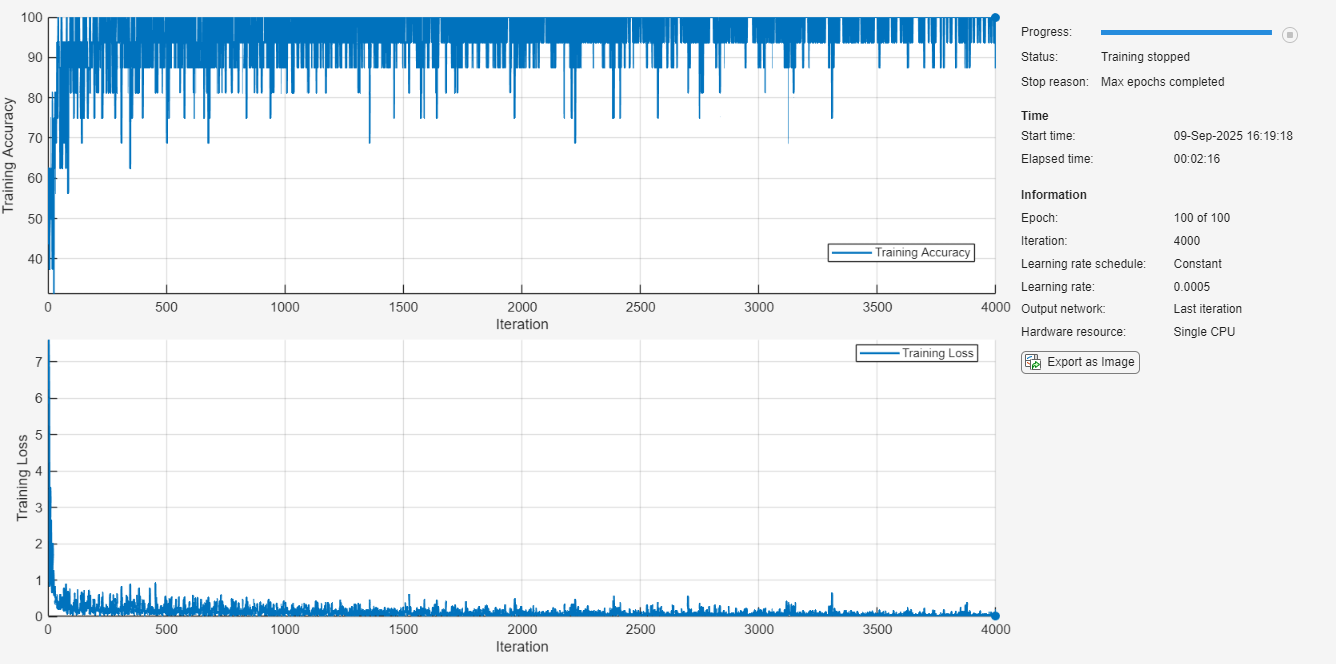

net = trainnet(augTrain, layers, "crossentropy", options);

## Schätzung

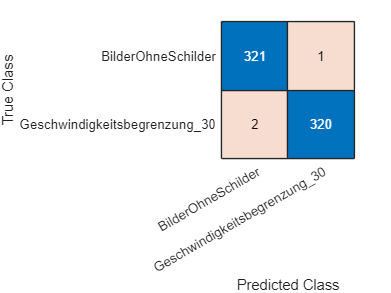


%Schätzung Trainingsdatensatz
tbl = readall(augTrain);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTrain = imdsTrain.Labels;
classNames = categories(TTrain);

XTrain = cat(4,imgs{:});
XTrain = single(XTrain);

outputs  = minibatchpredict(net,XTrain);
YTrain = onehotdecode(squeeze(outputs)',classNames,2);
confusionchart(TTrain,YTrain)

confMat = confusionmat(imdsTrain.Labels, YTrain);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 99.53%


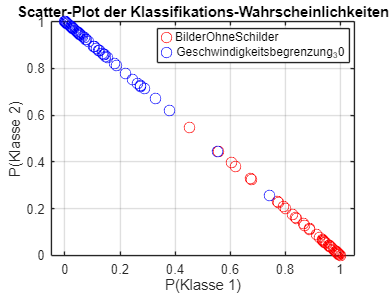


prob = squeeze(outputs); 

% 4) Scatterplot erstellen (mit Farbcode nach true Label)
figure;
gscatter(...
    prob(1,:), ...                    % X-Werte: P(Klasse 1)
    prob(2,:), ...                    % Y-Werte: P(Klasse 2)
    TTrain, ...                       % Gruppierung nach echtem Label
    'rb', ...                         % Farben: rot/blau
    'o', ...                          % Marker: Kreis
    8);                               % Markergröße

xlabel('P(Klasse 1)');
ylabel('P(Klasse 2)');
title('Scatter-Plot der Klassifikations-Wahrscheinlichkeiten');
legend(categories(TTrain), 'Location', 'best');
grid on;

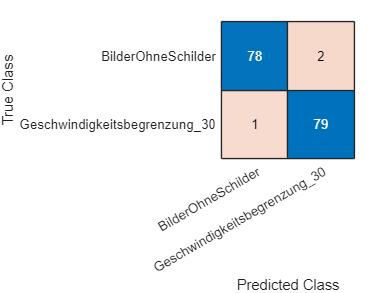

%axis square;

%Schätzung Testdatensatz
tbl = readall(augVal);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTest = imdsValidation.Labels;
classNames = categories(TTest);

XTest = cat(4,imgs{:});
XTest = single(XTest);

YTest = minibatchpredict(net,XTest);
YTest = onehotdecode(squeeze(YTest)',classNames,2);
confusionchart(TTest,YTest)

confMat = confusionmat(imdsValidation.Labels, YTest);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 98.12%


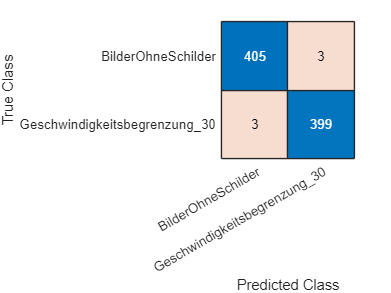


%Schätzung Gesamtbestand
tbl = readall(aug2);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTest2 = imdsSchilder.Labels;

XTest2 = cat(4,imgs{:});
XTest2 = single(XTest2);

YTest2 = minibatchpredict(net,XTest2);
YTest2 = onehotdecode(squeeze(YTest2)',classNames,2);

confusionchart(TTest2,YTest2)

confMat = confusionmat(imdsSchilder.Labels, YTest2);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 99.26%


## **Falsche Ergebnisse ausgeben**

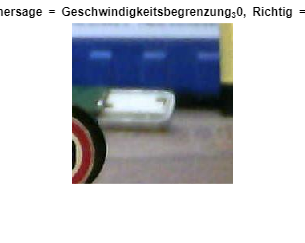

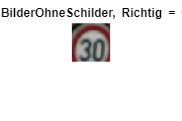

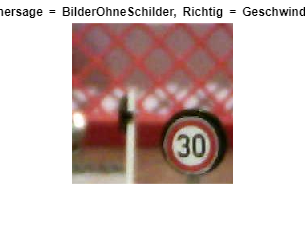

%Falsch erkantte Bilder anzeigen
trueLabelsTrain = imdsTrain.Labels;
trueLabelsVali = imdsValidation.Labels;
trueLabelsVali2 = imdsSchilder.Labels;

wrongIdxtrain = find(YTrain ~= trueLabelsTrain);
wrongIdxVali = find(YTest ~= trueLabelsVali);
wrongIdxVali2 = find(YTest2 ~= trueLabelsVali2);


for i = 1:length(wrongIdxtrain)
    img = readimage(imdsTrain, wrongIdxtrain(i));
    figure;
    imshow(img);
    title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
        string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
end

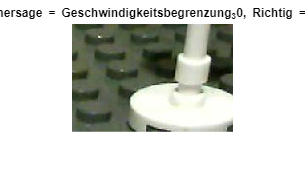

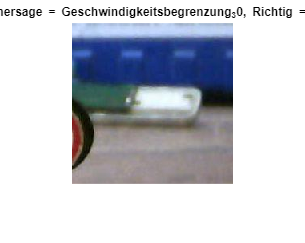

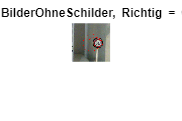


for i = 1:length(wrongIdxVali)
    img = readimage(imdsValidation, wrongIdxVali(i));
    figure;
    imshow(img);
    title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
        string(YTest(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
end


dateiname = imdsSchilder.Files(wrongIdxVali2);
% for i = 1:length(wrongIdxVali2)
%     img = readimage(imdsSchilder, wrongIdxVali2(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(YTest2(wrongIdxVali2(i))), string(trueLabelsVali2(wrongIdxVali2(i)))));
% end

## Evaluierung


exportNetworkToTensorFlow(net,"tf_model")
save('meinNetz.mat', 'net');

